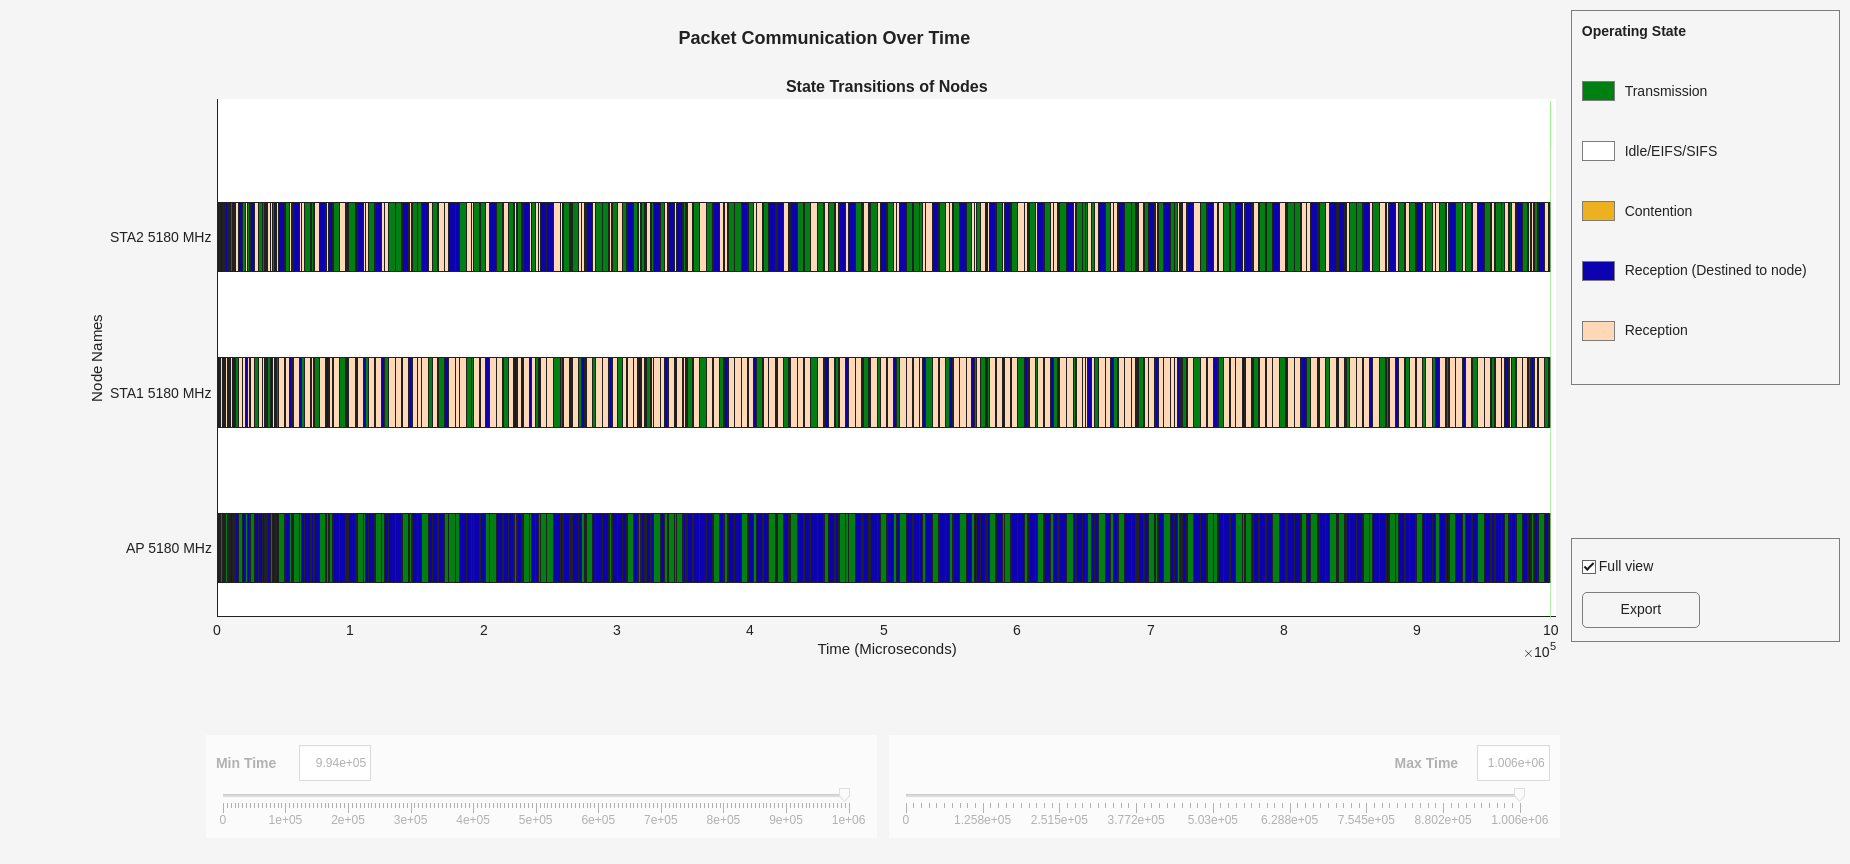

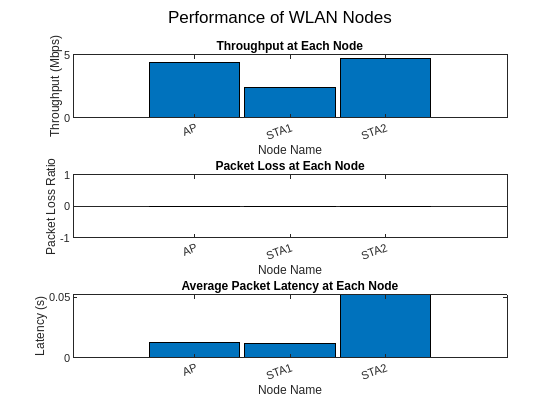

% --[Check if the Comm Toolbox is installed]--
wirelessnetworkSupportPackageCheck;

% --[Configure Simulation Parameters]--

% Set the seed to 1 : effects backoff counter selection (L2), packet reception success (L1)
rng(1,"combRecursive");

% Set the simulation time (in seconds)
simulationTime = 1;

% To visualize a live state transition for all the nodes
enablePacketVisualization = true;

% To view the node perfornance visualization
enableNodePerformancePlot = true;

% Modeling full MAC and PHY processing
MACFrameAbstraction = false;
PHYAbstractionMethod = "none";

% Packet Capture for analysis
capturePacketsFlag = true;

% Packets Arrival Rates (packets per second)
apToSta1ArrivalRate = 100;
sta1ToApArrivalRate = 200;
apToSta2ArrivalRate = 300;
sta2ToApArrivalRate = 400;
arrivalRates = [apToSta1ArrivalRate, sta1ToApArrivalRate;  % AP <-> STA1
                apToSta2ArrivalRate, sta2ToApArrivalRate]; % AP <-> STA2

% Packet Size
packetSize = 1500; % in bytes
% dataRate = (apToSta1ArrivalRate * packetSize * 8)/1000; % Compute DataRate in Kbps

% Buffer Size
bufferSize = 500;

% --[Configure WLAN Scenario]--
% Initialize the Wireless Network Simulator
networkSimulator = wirelessNetworkSimulator.init;

% Number Nodes
numNodes = 3;
numSTAs = numNodes-1;

% Nodes Positions
apPosition = [0 0 0];
staPositions = [((30/numSTAs).*(1:numSTAs))' ((30/numSTAs).*(numSTAs:-1:1))' zeros(numSTAs,1)];

% Nodes Configuration
apConfig = wlanDeviceConfig(Mode="AP", ...
    MCS=1, ...
    TransmitPower=20, ...
    TransmissionFormat="HT-Mixed", ...
    TransmitQueueSize=bufferSize); % AP device configuration
staConfig = wlanDeviceConfig(Mode="STA", ...
    MCS=1, ...
    TransmitPower=20, ...
    TransmissionFormat="HT-Mixed", ...
    TransmitQueueSize=bufferSize);    % STA device configuration

% Nodes Creation
apNode = wlanNode(Name="AP", ...
    Position=apPosition, ...
    DeviceConfig=apConfig, ...
    PHYAbstractionMethod=PHYAbstractionMethod, ...
    MACFrameAbstraction=MACFrameAbstraction);

staNodes = wlanNode(Name="STA"+(1:numSTAs), ...
    Position=staPositions, ...
    DeviceConfig=staConfig, ...
    PHYAbstractionMethod=PHYAbstractionMethod, ...
    MACFrameAbstraction=MACFrameAbstraction);

% sta2Node = wlanNode(Name="STA2", ...
%     Position=[20 0 0], ...
%     DeviceConfig=staConfig, ...
%     PHYAbstractionMethod=PHYAbstractionMethod, ...
%     MACFrameAbstraction=MACFrameAbstraction);

% Create WLAN network
nodes = [apNode staNodes];

% Verify if all nodes are configured properly
hCheckWLANNodesConfiguration(nodes);

% Association and Application Traffic
associateStations(apNode, staNodes);

%%% % --[Configure External Application Traffic : On-Off,Video,Voice,FTP]---

%%% % Generate UP and DOWN links On-Off application traffics for each AP-STA pair
% Loop through stations to create traffic sources
for i = 1:numSTAs
    % Downlink (AP to STA)
    trafficDown = networkTrafficOnOff( ...
        DataRate=(arrivalRates(i,1) * packetSize * 8)/1000, ...
        PacketSize=packetSize, ...
        OnTime=Inf, OffTime=0);
    addTrafficSource(apNode, trafficDown, DestinationNode=staNodes(i), AccessCategory=0);

    % Uplink (STA to AP)
    trafficUp = networkTrafficOnOff( ...
        DataRate=(arrivalRates(i,2) * packetSize * 8)/1000, ...
        PacketSize=packetSize, ...
        OnTime=Inf, OffTime=0);
    addTrafficSource(staNodes(i), trafficUp, DestinationNode=apNode, AccessCategory=0);
end 
% trafficSourceApToSta1 = networkTrafficOnOff( ...
%     DataRate=(apToSta1ArrivalRate * packetSize * 8)/1000, ...
%     PacketSize=packetSize, ...
%     OnTime=Inf,OffTime=0);
% 
% trafficSourceSta1ToAp = networkTrafficOnOff( ...
%     DataRate=(sta1ToApArrivalRate * packetSize * 8)/1000, ...
%     PacketSize=packetSize, ...
%     OnTime=Inf,OffTime=0);
% 
% trafficSourceApToSta2 = networkTrafficOnOff( ...
%     DataRate=(apToSta2ArrivalRate * packetSize * 8)/1000, ...
%     PacketSize=packetSize, ...
%     OnTime=Inf,OffTime=0);
% 
% trafficSourceSta2ToAp = networkTrafficOnOff( ...
%     DataRate=(sta2ToApArrivalRate * packetSize * 8)/1000, ...
%     PacketSize=packetSize, ...
%     OnTime=Inf,OffTime=0);
% 
% addTrafficSource(apNode,trafficSourceApToSta1,DestinationNode=sta1Node,AccessCategory=0);
% addTrafficSource(sta1Node,trafficSourceSta1ToAp,DestinationNode=apNode,AccessCategory=0);
% addTrafficSource(apNode,trafficSourceApToSta2,DestinationNode=sta2Node,AccessCategory=0);
% addTrafficSource(sta2Node,trafficSourceSta2ToAp,DestinationNode=apNode,AccessCategory=0);

% % Wireless Channel
% channel = hSLSTGaxMultiFrequencySystemChannel(nodes)
% addChannelModel(networkSimulator, channel.ChannelFcn);

%%% % Add Mobility To Nodes : STA for example (but can be added to any node)
%%% addMobility(station)

% --[Export WLAN MAC Frames to PCAP]--
if capturePacketsFlag
    clear capturePacketsObj;                       % Clear existing helper object
    capturePacketsObj = hExportWLANPackets(nodes);
end

% --[Simulation and Results]--

% Add the nodes to the Wireless Network Simulator
addNodes(networkSimulator,nodes)

% View the state transition plot
if enablePacketVisualization
    packetVisObj = hPlotPacketTransitions(nodes,simulationTime,FrequencyPlotFlag=false);
end

% View the node performance visualiszation
if enableNodePerformancePlot
    performancePlotObj = hVisualizePerformance(nodes,simulationTime);
end

% Run the simulator
run(networkSimulator, simulationTime);

% Retrieve the APP, MAC and PHY statistics at each node
apStats = statistics(apNode);
stasStats = statistics(staNodes);
% Delete the PCAP objects
if capturePacketsFlag
    delete(capturePacketsObj.PCAPObjList);
end

disp(apStats.App)

    TransmittedPackets: 402
      TransmittedBytes: 603000
       ReceivedPackets: 595
         ReceivedBytes: 892500



stasStats(1).Name,stasStats(1).App

ans = "STA1"

ans = struct with fields:
    TransmittedPackets: 201
      TransmittedBytes: 301500
       ReceivedPackets: 100
         ReceivedBytes: 150000


stasStats(2).Name,stasStats(2).App

ans = "STA2"

ans = struct with fields:
    TransmittedPackets: 401
      TransmittedBytes: 601500
       ReceivedPackets: 269
         ReceivedBytes: 403500


disp(apStats.MAC)

            TransmittedDataFrames: 369
          TransmittedPayloadBytes: 553500
      SuccessfulDataTransmissions: 369
          RetransmittedDataFrames: 0
                TransmittedAMPDUs: 115
             TransmittedRTSFrames: 119
           TransmittedMURTSFrames: 0
             TransmittedCTSFrames: 177
           TransmittedMUBARFrames: 0
             TransmittedAckFrames: 0
        TransmittedBlockAckFrames: 177
    TransmittedBasicTriggerFrames: 0
               ReceivedDataFrames: 595
             ReceivedPayloadBytes: 892500
                   ReceivedAMPDUs: 177
                ReceivedRTSFrames: 177
              ReceivedMURTSFrames: 0
                ReceivedCTSFrames: 115
              ReceivedMUBARFrames: 0
                ReceivedAckFrames: 0
           ReceivedBlockAckFrames: 115
       ReceivedBasicTriggerFrames: 0
           ReceivedFCSValidFrames: 1002
                 ReceivedFCSFails: 9
        ReceivedDelimiterCRCFails: 0



stasStats(1).Name,stasStats(1).MAC

ans = "STA1"

ans = struct with fields:
            TransmittedDataFrames: 200
          TransmittedPayloadBytes: 300000
      SuccessfulDataTransmissions: 200
          RetransmittedDataFrames: 0
                TransmittedAMPDUs: 70
             TransmittedRTSFrames: 83
           TransmittedMURTSFrames: 0
             TransmittedCTSFrames: 58
           TransmittedMUBARFrames: 0
             TransmittedAckFrames: 0
        TransmittedBlockAckFrames: 58
    TransmittedBasicTriggerFrames: 0
               ReceivedDataFrames: 764
             ReceivedPayloadBytes: 150000
                   ReceivedAMPDUs: 222
                ReceivedRTSFrames: 58
              ReceivedMURTSFrames: 0
                ReceivedCTSFrames: 70
              ReceivedMUBARFrames: 0
                ReceivedAckFrames: 0
           ReceivedBlockAckFrames: 70
       ReceivedBasicTriggerFrames: 0
           ReceivedFCSValidFrames: 1454
                 ReceivedFCSFails: 0
        ReceivedDelimiterCRCFails: 0


stasStats(2).Name,stasStats(2).MAC

ans = "STA2"

ans = struct with fields:
            TransmittedDataFrames: 395
          TransmittedPayloadBytes: 592500
      SuccessfulDataTransmissions: 395
          RetransmittedDataFrames: 0
                TransmittedAMPDUs: 107
             TransmittedRTSFrames: 117
           TransmittedMURTSFrames: 0
             TransmittedCTSFrames: 57
           TransmittedMUBARFrames: 0
             TransmittedAckFrames: 0
        TransmittedBlockAckFrames: 57
    TransmittedBasicTriggerFrames: 0
               ReceivedDataFrames: 569
             ReceivedPayloadBytes: 403500
                   ReceivedAMPDUs: 185
                ReceivedRTSFrames: 57
              ReceivedMURTSFrames: 0
                ReceivedCTSFrames: 107
              ReceivedMUBARFrames: 0
                ReceivedAckFrames: 0
           ReceivedBlockAckFrames: 107
       ReceivedBasicTriggerFrames: 0
           ReceivedFCSValidFrames: 1228
                 ReceivedFCSFails: 0
        ReceivedDelimiterCRCFails: 0


disp(apStats.PHY)

         TransmittedPackets: 588
    TransmittedPayloadBytes: 577076
            ReceivedPackets: 593
       ReceivedPayloadBytes: 922576
             DroppedPackets: 4



stasStats(1).Name,stasStats(1).PHY

ans = "STA1"

ans = struct with fields:
         TransmittedPackets: 269
    TransmittedPayloadBytes: 311388
            ReceivedPackets: 912
       ReceivedPayloadBytes: 1188264
             DroppedPackets: 13


stasStats(2).Name,stasStats(2).PHY

ans = "STA2"

ans = struct with fields:
         TransmittedPackets: 338
    TransmittedPayloadBytes: 611468
            ReceivedPackets: 844
       ReceivedPayloadBytes: 888204
             DroppedPackets: 9


performancePlotObj.getAveragePacketLatency()

ans =     1.0000    0.0131         0
    2.0000    0.0120         0
    3.0000    0.0520         0


performancePlotObj.getPacketLossRatio()

ans =      1     0     0
     2     0     0
     3     0     0


performancePlotObj.getThroughput()

ans =     1.0000    4.4280         0
    2.0000    2.4000         0
    3.0000    4.7400         0
